# PEM Grupo 3: Gradient Descend (Fletcher-Reeves)

**Elaborado por:**

Federico Banoy Restrepo

Juan David Rengifo Castro

Salomón Cardeño Luján

## Problema

Implementar en MatLab el método de optimización seleccionado para una estructura arx111 $\left(G\left(z\right)=\frac{{z\;b}_1 }{z+a_1 }\right)$. Graficar la convergencia y recorrido del algoritmo excitándolo con una señal PRBS y aplicando distintos niveles de ruido.

## Grandiente descente

El **gradiente descendente** hace parte de los métodos de primer orden, los cuales emplean información sobre el gradiente de la **función de costo** $\nabla V\left(\mathit{\mathbf{x}}\right)=\frac{\partial }{\partial \mathit{\mathbf{x}}}V\left(\mathit{\mathbf{x}}\right)$. 

Este método se basa en la idea de iterativamente, *avanzar en la dirección de máxima reducción de la función de costo*. Para calcular dicha dirección se suele emplear el **vector de búsqueda,** denotado por $s\left(k\right)$, se define como el inverso aditivo del gradiente de la función de costos normalizado en norma euclidea.


$$\mathit{\mathbf{s}}\left(k\right)=-\;$$

$$\frac{\nabla V\left(\mathit{\mathbf{x}}\left(k\right)\right)}{\left\|\nabla V\left(\mathit{\mathbf{x}}\left(k\right)\right){\left\|\right.}_2 \right.}$$


Así las cosas, el algoritmo considera la información de la iteración anterior para mejorar la estimación, tal y como se muestra a continuación

$\mathit{\mathbf{x}}\left(k+1\right)=\mathit{\mathbf{x}}\left(k\right)+\alpha \cdot \mathit{\mathbf{s}}\left(k\right);\;\;\;\;\;\mathit{\mathbf{x}}\left(0\right)={\mathit{\mathbf{x}}}_0$,

donde $\alpha$ es el *tamaño de paso* y${\;\mathit{\mathbf{x}}}_0$ las *condiciones iniciales* . Este parámetro es fundamental para el desempeño del método puesto que regula la velocidad de cambio en cada iteración. Un tamaño de paso muy pequeño es más preciso, pero puede resultar muy costoso en tiempo de computo. Por el contrario un tamaño de paso muy grande será muy eficiente en tiempo pero puede generar estimaciones muy poco precisas. Por lo tanto, elección de este parámetro no debe tomarse a la ligera. Cabe resaltar, que existen múltiples métodos para escoger un $\alpha$ apropiado y puede ser fijo o variable.

### Fletcher-Reeves

En aras de lograr una buena estimación con una mejor convergencia, Fletcher & Reeves (1964) propusieron una modificación al gradiente descendente tradicional mediante el uso de gradientes conjugados, alcanzando así una convergencia cuadrática para funciones objetivos cuadráticas, tales como el error cuadrático medio (MSE).

El método modifica el vector de búsqueda como sigue:

$\mathit{\mathbf{s}}\left(k\right)=-\nabla V\left(\mathit{\mathbf{x}}\left(k\right)\right)+\beta \left(k\right)\mathit{\mathbf{s}}\left(k-1\right)$,

donde,


$$\beta \left(k\right)=\frac{{\left\lbrack \nabla V\left(\mathit{\mathbf{x}}\left(k\right)\right)\right\rbrack }^T \left\lbrack \nabla V\left(\mathit{\mathbf{x}}\left(k\right)\right)\right\rbrack }{{\left\lbrack \nabla V\left(\mathit{\mathbf{x}}\left(k-1\right)\right)\right\rbrack }^T \left\lbrack \nabla V\left(\mathit{\mathbf{x}}\left(k-1\right)\right)\right\rbrack }\;$$


Antes de proceder a la implementación, vale la pena hacer algunos comentarios. 

- Se sugiere emplear un método para escoger valores iniciales adecuados.

- El algoritmo es sensible a impresiciones numéricas, por lo tanto es recomendable reiniciar el algoritmo durante la optimización.

- Es recomendable escoger un número de iteraciones máximas apropiado.

Lamentablemente, dadas las restricciones de tiempo, no se implementaron algoritmos para la elección de parámetros adecuados.

**Nota:** Una sucesión converge con orden $q$ a $\epsilon$ si $\lim_{k\longrightarrow \infty } \frac{{\left|x\right.}_{k+1} -\varepsilon \left|\right.}{\left|x_k -\varepsilon {\left|\right.}^q \right.}=\mu >0\ldotp$

## Metodología

### ¿Qué tenemos?

- Función de transferencia discreta $G\left(z\right)=\frac{{z\;b}_1 }{z+a_1 }$ asociada a un ARX110.

- Entrada de señal discreta binaria [PRBS](https://www.mathworks.com/help/serdes/ref/prbs.html).

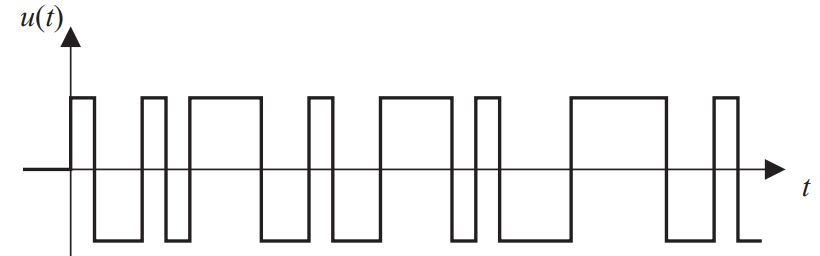

### Plan

- Definición explicita del modelo.

- Cálculo analítico del vector de busqueda

- Implementación.

- Análisis de convergencia.

## Solución

### Modelo

La estructura de un modelo arx110 ($a,b,$ exponente de $q$ en el numerador) es la siguiente


$$y\left(k\right)=\frac{b_1 q^{-0} }{1+a_1 q^{-1} }u\left(k\right)+\frac{1}{1+a_1 q^{-1} }e\left(k\right)$$



$$y\left(k\right)+a_1 y\left(k-1\right)=b_1 u\left(k\right)+e\left(k\right)$$



$$y\left(k\right)=-a_1 y\left(k-1\right)+b_1 u\left(k\right)+e\left(k\right)$$


### Estimación del error (e en el código)

De la expresión anterior, el error $e\left(t\right)$ se puede estimar como


$$e\left(k\right)=y\left(k\right)+a_1 y\left(k-1\right)-b_1 u\left(k\right)$$


## Gradiente de la función de costo (S1 y S2 en el código)

Sabemos que la función de costo en nuestro caso es $V\left(\theta \;\right)=\frac{1}{N}\sum_{t=1}^N e^2 \left(t\right)$, lo cual implica que


$$\frac{\partial \;V}{\partial \;a_1 }=\frac{2}{N}\sum_{t=1}^N e\left(t\right)\frac{\partial \;e\left(t\right)}{{\partial \;a}_1 },\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{\partial \;V}{\partial \;b_1 }=\frac{2}{N}\sum_{t=1}^N e\left(t\right)\frac{\partial \;e\left(t\right)}{{\partial \;b}_1 }\;$$


Luego, como $\frac{\partial e\left(t\right)}{\partial \;a_1 }=y\left(t-1\right)$ y $\frac{\partial e\left(t\right)}{\partial \;b_1 }=-u\left(t\right)$, entonces


$$\frac{\partial \;V}{\partial \;a_1 }=\frac{2}{N}\sum_{t=1}^N e\left(t\right)y\left(t-1\right)=\frac{2}{N}S_1 \left(k\right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{\partial \;V}{\partial \;b_1 }=-\frac{2}{N}\sum_{t=1}^N e\left(t\right)u\left(t\right)=-\frac{2}{N}S_2 \left(k\right)$$



$$\nabla V\left(\mathit{\mathbf{x}}\left(k\right)\right)={\left\lbrack \frac{2}{N}S_1 \left(k\right),-\frac{2}{N}S_2 \left(k\right)\right\rbrack }^T \ldotp$$


### Estimación de los parámetros $a_1$ y $b_1$

Realizamos la estimación de los parámetros del modelos, es decir, $\theta =\left\lbrack a_1 ,b_1 \right\rbrack$.

#### Iteración 1

Para la primera iteración empleamos el gradiente descendentes básico, es decir,

$a_1 \left(k+1\right)=a_1 \left(k\right)+\alpha_k$$s_a \left(k\right)$, donde $s_a \left(k\right)=-$$\frac{\partial \;V}{\partial \;a_1 }$

$b_1 \left(k+1\right)=b_1 \left(k\right)+\alpha_k s_b \left(k\right)$, donde $s_b \left(k\right)=-$$\frac{\partial \;V}{\partial \;b_1 }$.

#### Iteración 2 en adelante

Desde la segunda iteración empleamos la propuesta de Fletcher-Reeves, pues antes no tiene sentido. Veamos cual es el vector de busqueda.


$$a_1 \left(k+1\right)=a_1 \left(k\right)+\alpha_k$$

$$s_a \left(k\right)$$



$$b_1 \left(k+1\right)=b_1 \left(k\right)+\alpha_k$$

$$s_b \left(k\right)$$


donde:

 
$$s_a \left(k\right)=$$

$$-\frac{\partial \;V}{\partial \;a_1 }+\beta \;\left(k\right)s_a \left(k-1\right)$$



$$s_b \left(k\right)=$$

$$-\frac{\partial \;V}{\partial \;b_1 }+\beta \;\left(k\right)s_b \left(k-1\right)$$



$$\beta \;\left(k\right)=$$

$$\frac{{\left\lbrack \frac{\partial \;V}{\partial \;a_1 },\frac{\partial \;V}{\partial \;b_1 }\right\rbrack }^T \cdot {\left\lbrack \frac{\partial \;V}{\partial \;a_1 },\frac{\partial \;V}{\partial \;b_1 }\right\rbrack }^T }{{\left\lbrack \frac{\partial \;V}{\partial \;a_1 }\left(k-1\right),\frac{\partial \;V}{\partial \;b_1 }\left(k-1\right)\right\rbrack }^T \cdot {\left\lbrack \frac{\partial \;V}{\partial \;a_1 }\left(k-1\right),\frac{\partial \;V}{\partial \;b_1 }\left(k-1\right)\right\rbrack }^T }$$



$$=\frac{{\frac{\partial \;V}{\partial \;a_1 }}^2 +{\frac{\partial \;V}{\partial \;b_1 }}^2 }{{\frac{\partial \;V}{\partial \;a_1 }\left(k-1\right)}^2 +{\frac{\partial \;V}{\partial \;b_1 }\left(k-1\right)}^2 }=\frac{{\left(\frac{2}{N}\sum_{t=1}^N e\left(t\right)y\left(t-1\right)\right)}^2 +{\left(-\frac{2}{N}\sum_{t=1}^N e\left(t\right)u\left(t\right)\right)}^2 }{{\left(\frac{2}{N}\sum_{t=1}^N e\left(t,k-1\right)y\left(t-1,k-1\right)\right)}^2 +{\left(-\frac{2}{N}\sum_{t=1}^N e\left(t,k-1\right)u\left(t,k-1\right)\right)}^2 }$$



$$=\frac{{\left(\sum_{t=1}^N e\left(t\right)y\left(t-1\right)\right)}^2 -{\left(\sum_{t=1}^N e\left(t\right)u\left(t\right)\right)}^2 }{{\left(\sum_{t=1}^N e\left(t,k-1\right)y\left(t-1,k-1\right)\right)}^2 -{\left(\sum_{t=1}^N e\left(t,k-1\right)y\left(t-1,k-1\right)\right)}^2 }=\frac{{\left(S_1 \left(k\right)\right)}^2 -{\left(S_2 \left(k\right)\right)}^2 }{{\left(S_1 \left(k-1\right)\right)}^2 -{\left(S_2 \left(k-1\right)\right)}^2 }$$


Así tenemos por vector de busqueda, 

$\mathit{\mathbf{s}}\left(k\right)=\left\lbrack a_1 \left(k\right)+\alpha \left(k\right)s_a \left(k\right),\;b_1 \left(k\right)+\alpha \left(k\right)s_b \left(k\right)\right\rbrack$.

## Tamaño de paso $\alpha_k$

De acuerdo con el [análisis de convergencia](https://www.cs.cmu.edu/~ggordon/10725-F12/scribes/10725_Lecture5.pdf) empleado para el método de gradiente descendente es posible que el tamaño de paso $\alpha_k <\frac{1}{2k}$. En este caso, se considera la elección heurística de $\alpha_k =\frac{1}{2k}$ (aún si se trata de la extensión del método), donde $k$ es la iteración. Esto resulta menos costoso computacionalmente y más simple que utilizar un método de optimización de una dimensión para encontrar el $\alpha_k$ óptimo, lo cual es el procedimiento usual.

## Código

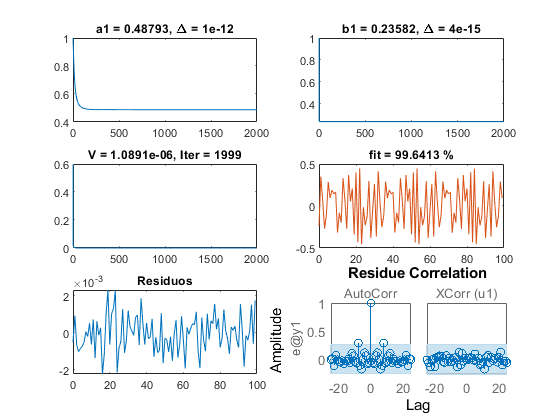

% Simulación OE

a1 = 0.4876; b1 = 0.2357;
A_error = 0.001; % Amplitud del error
N = 100; % Número de datos experimentales
z = tf('z', 'Ts', 1); Gd = b1*z/(z+a1); % Modelo
u = 2*(prbs(5,N, [1 0 1 0 0])-0.5); % Entrada experimental PRBS
y = lsim(Gd,u,(0:1:N-1)); % Salida experimental
rng(1); % Para generar siempre la misma secuencia aleatoria
y = y + A_error*randn(N,1); % Señal con ruido (modelo OE de perturbación)

% Método numérico del gradiente descendente (Fletcher-Reeves) con modelo ARX110
M = 2000; % Número máximo de iteraciones
a1 = zeros(1,M); b1 = zeros(1,M); V = zeros(1,M);
a1(1) = 1; % Valor inicial de a1
b1(1) = 1; % Valor inicial de b1
tol = 1e-12; % Criterio de parada según exactitud de los parámetros
Vmin = 1e-12; % Criterio de parada según la función de coste

for i=1:M-1 % Proceso de estimación de los parémetros
    S1 = 0; S2 = 0; V1 = 0;
    S1_ant = 0; S2_ant = 0;
    for j=2:N
        e = y(j) + a1(i)*y(j-1) - b1(i)*u(j); % Predicción del error
        S1 = S1 + e*y(j-1);
        S2 = S2 + e*u(j);
        V1 = V1 + e^2;
        
        if i >= 2
            e_ant = y(j) + a1(i-1)*y(j-1) - b1(i-1)*u(j); % Predicción del error
            S1_ant = S1_ant + e_ant*y(j-1);
            S2_ant = S2_ant + e_ant*u(j);
        end
        
    end
    V(i) = V1/N; % Función de coste
    if V(i) < Vmin
        a1 = a1(1:i);
        b1 = b1(1:i);
        V = V(1:i);
        iter = i;
        break
    end
    if i==1
        s_a = -(2*S1/N);
        s_b = -(-2*S2/N);
    else
        beta = (S1^2-S2^2)/(S1_ant^2-S2_ant^2);
        s_a = -(2*S1/N) + beta*s_a;
        s_b = -(-2*S2/N) + beta*s_b;
    end
    alphak = 1/(2*i); % Longitud de paso dinámica
    a1(i+1) = a1(i) + alphak*s_a;
    b1(i+1) = b1(i) + alphak*s_b;
    if ((abs(a1(i+1)-a1(i)) <= tol) && (abs(b1(i+1)-b1(i)) <= tol))
        a1 = a1(1:i+1);
        b1 = b1(1:i+1);
        V1 = 0;
        iter = i+1;
        for j=2:N
            e = y(j) + a1(i+1)*y(j-1) - b1(i+1)*u(j);
            V1 = V1 + e^2;
        end
        V(i+1) = V1/N;
        V = V(1:i+1);
        break
    end
    iter = M-1;
end

arx110 = z*b1(iter)/(z + a1(iter));
[yest, t] = lsim(arx110,u,(0:1:N-1));
test_data = iddata(y, u', 1);
res = y - yest;
fit = (1 - norm(y - yest)/norm(y - mean(y)) )*100;
figure("Name",'Resultados')
subplot(3,2,2), plot(b1), title([ 'b1 = ' num2str(b1(iter)) ', \Delta = ' num2str( abs( b1(iter)-b1(iter-1) ),1 ) ])
subplot(3,2,1), plot(a1), title([ 'a1 = ' num2str(a1(iter)) ', \Delta = ' num2str( abs( a1(iter)-a1(iter-1) ),1 ) ])
subplot(3,2,3), plot(V), title(['V = ' num2str(V(iter)) , ', Iter = ' num2str(iter)])
subplot(3,2,4), plot(t,y,t,yest), title(['fit = ' num2str(fit) ' %'])
subplot(3,2,5), plot(t,res), title('Residuos')
subplot(3,2,6), resid(test_data, arx110);

## Bibliografia

FLETCHER,  R., & REEVES, C. 1964 Function  minimization  by conjugate  gradients. Comput. J. 7,149-154. 

- [Link oficial](https://doi.org/10.1093/comjnl/7.2.149)

- [Sci-Hub](https://sci-hub.se/https://doi.org/10.1093/comjnl/7.2.149)

GORDON, G., & TIBSHIRANI, R. Fall 2012 10-725 Optimization course Lecture 5: Gradient Descent Revisited, School of Computer Science, Carneige Mellon University.

- [Link oficial](https://www.cs.cmu.edu/~ggordon/10725-F12/scribes/10725_Lecture5.pdf)